x0 = [-2, 1];
ub = [2.5, 2.5];
lb = -ub;

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.069603e+00    0.000e+00    2.917e+00
    1       6    1.567083e+00    0.000e+00    1.129e+00    2.213e+00
    2       9    8.437887e-01    0.000e+00    1.161e+00    1.001e+00
    3      12    7.819411e-01    0.000e+00    1.514e+00    8.235e-01
    4      15    5.769648e-01    0.000e+00    8.243e-01    7.410e-01
    5      18    3.362941e-01    0.000e+00    8.577e-01    2.679e-01
    6      23    2.761278e-01    0.000e+00    7.379e-01    1.460e-01
    7      26    2.117204e-01    0.000e+00    4.471e-01    1.124e-01
    8      29    1.210045e-01    0.000e+00    1.857e+00    4.412e-01
    9      32    7.687297e-02    0.000e+00    1.496e+00    1.874e-01
   10      35    3.306371e-02    0.000e+00    8.603e-02    1.169e-01
   11      38    2.618171e-02    0.000e+00    1.333e+00    2.155e-01
   12      41    1.480472e-02    0.000e+00    2

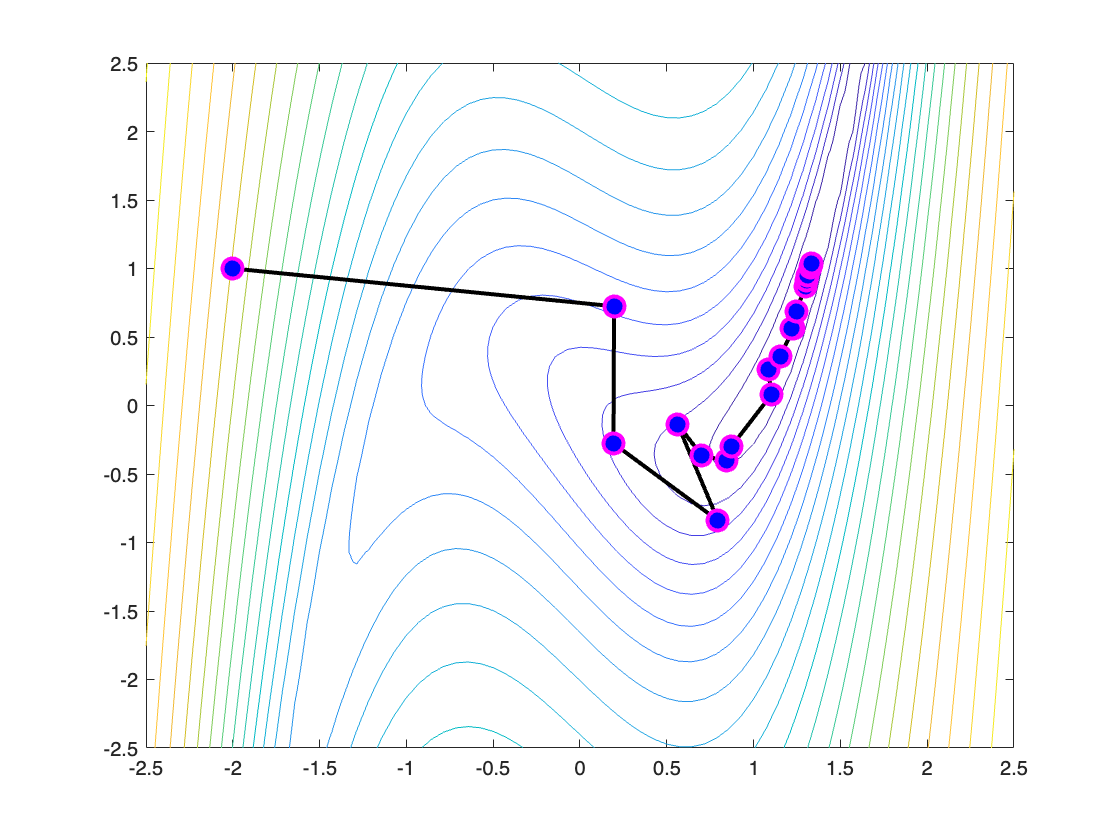

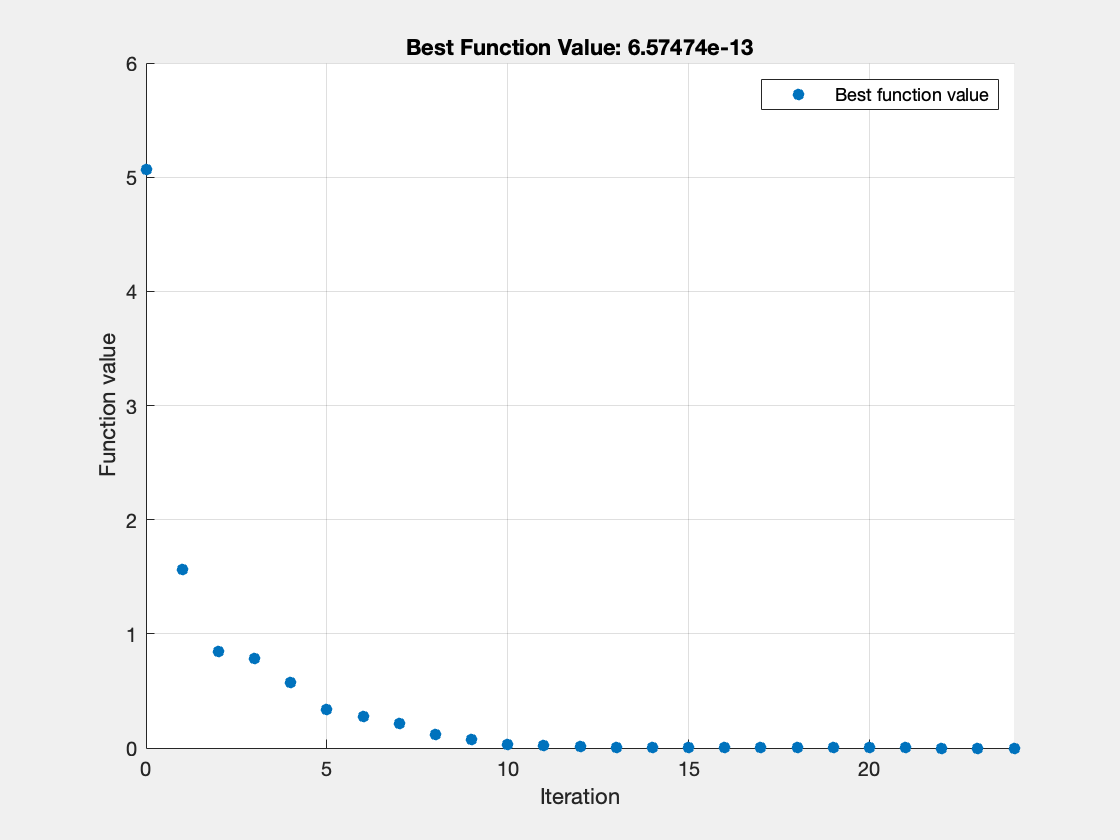

% Set nondefault solver options
options3 = optimoptions("fmincon","OutputFcn",@plotUpdate,"Display","iter",...
    "PlotFcn","optimplotfvalconstr");

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],lb,ub,[],...
    options3);


% Clear variables
clearvars options3

function f = objectiveFcn(optimInput)
% Example:
% Minimize Rosenbrock's function
% f = 100*(y - x^2)^2 + (1 - x)^2

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
f = log( 1 + 3*(y - (x.^3 - x)).^2 + (x - 4/3).^2 );
end

